# Specify Truncation Order

Find the Maclaurin series expansion for `f = sin(x)/x`. The default truncation order is 6. The Taylor series approximation of this expression does not have a fifth-degree term, so `taylor` approximates this expression with the fourth-degree polynomial.

syms x
f = sin(x)/x;
T6 = taylor(f,x);

Use `Order` to control the truncation order. For example, approximate the same expression up to the orders 7 and 9.

T8 = taylor(f,x,'Order',8);
T10 = taylor(f,x,'Order',10);

Plot the original expression `f` and its approximations `T6`, `T8`, and `T10`. Note how the accuracy of the approximation depends on the truncation order.

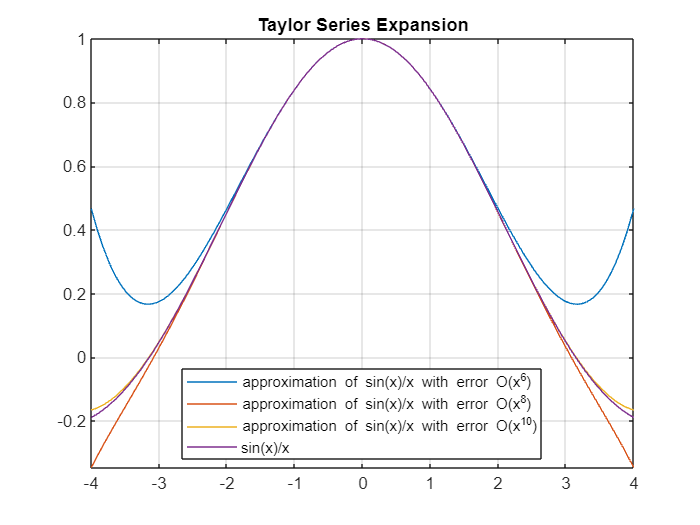

fplot([T6 T8 T10 f])
xlim([-4 4])
grid on
legend('approximation of sin(x)/x with error O(x^6)', ...
       'approximation of sin(x)/x with error O(x^8)', ...
       'approximation of sin(x)/x with error O(x^{10})', ...
       'sin(x)/x','Location','Best')
title('Taylor Series Expansion')

*Copyright 2012 The MathWorks, Inc.*